# WP1

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP1".

## Parametri del modello

% x1: concentrazione del glucosio
% x2: concentrazione di insulina nei liquidi interstiziali 
clear all, clc;
p1 = 0.0151; % tasso base di rimozione del glucosio dal sangue
p2 = 0.0313; % tasso rimozione del glucosio dovuto all'insulina
p3 = 0.0097;
ge = 0.97;
ie = 0.003;
u_eq = 1.003;

## Analisi del sistema a ciclo aperto

#### Plot dei punti di equilibrio al variare dell'ingresso u

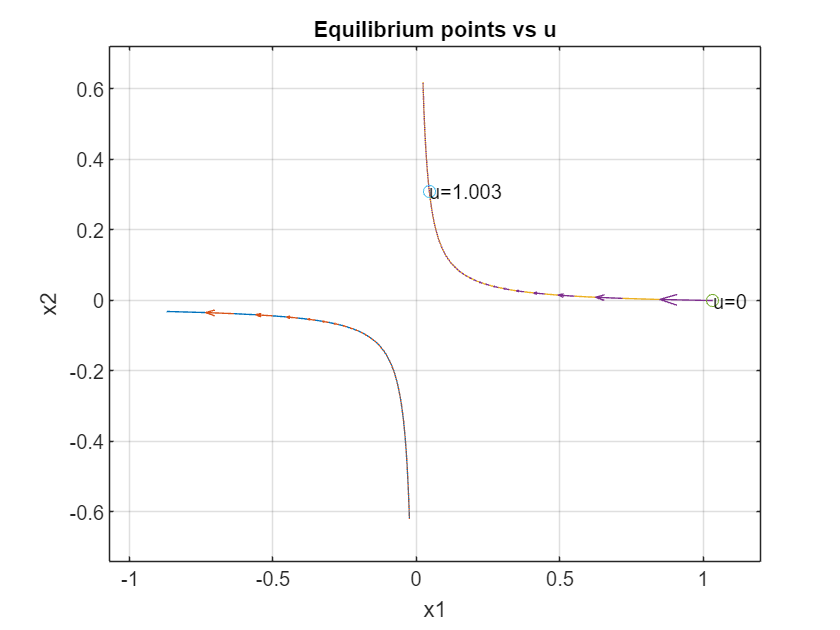

figure;
[x1eq,x2eq] = get_equilibrium([-2:0.01:-0.1]);
directedplot(x1eq.',x2eq.');
hold on;
[x1eq,x2eq] = get_equilibrium([0:0.01:2]);
directedplot(x1eq.',x2eq.');
xlabel("x1");
ylabel("x2");
hold on;
% Plot dei punti notevoli u=0 e u=1.003
[x1eq0,x2eq0] = get_equilibrium(0);
[x1eq1,x2eq1] = get_equilibrium(1.003);
scatter(x1eq0,x2eq0);
text(x1eq0,x2eq0,'u=0');
scatter(x1eq1,x2eq1);
text(x1eq1,x2eq1,'u=1.003');
grid on;
title('Equilibrium points vs u');

xlim([-1.07 1.20])
ylim([-0.74 0.72])

#### Piani delle fasi a ciclo aperto per per u=0 e u=u_eq

matlab.apputil.run('PhasePlane');

Per visualizzare i piani delle fasi prodotti andare su 'Custom Library'>'Load' e caricare il file 'PhasePlaneLibrary.mat'. Dopodiché nel menù 'Custom Library' è possibile scegliere quale piano delle fasi visualizzare. I piani delle fasi forniti sono:

- plant-fixed-u: il processo simulato a ciclo aperto con u=u_eq

- plant-natural-response: il processo simulato a ciclo aperto con u=0

Altri piani delle fasi contenuti nel file vengono discussi in seguito. Nella sezione "axis limit" è possibile impostare i limiti degli assi e il tempo della simulazione.

#### Simulazione dell'evoluzione libera del sistema a ciclo aperto senza insulina

Si osservi che d'ora in avanti per simulare il sistema si sceglierà come lo stato iniziale per la variabile di stato $x_1$ (ovvero come livello iniziale di glucosio) un valore superiore al riferimento desiderato. Questo è fatto in maniera concorde alla realtà di interesse in quanto lo scopo del nostro sistema di controllo è quello di sfruttare l'azione dell'insulina per abbassare i livelli di glucosio nel sangue.

Adesso simuliamo l'evoluzione libera del sistema in assenza di insulina.

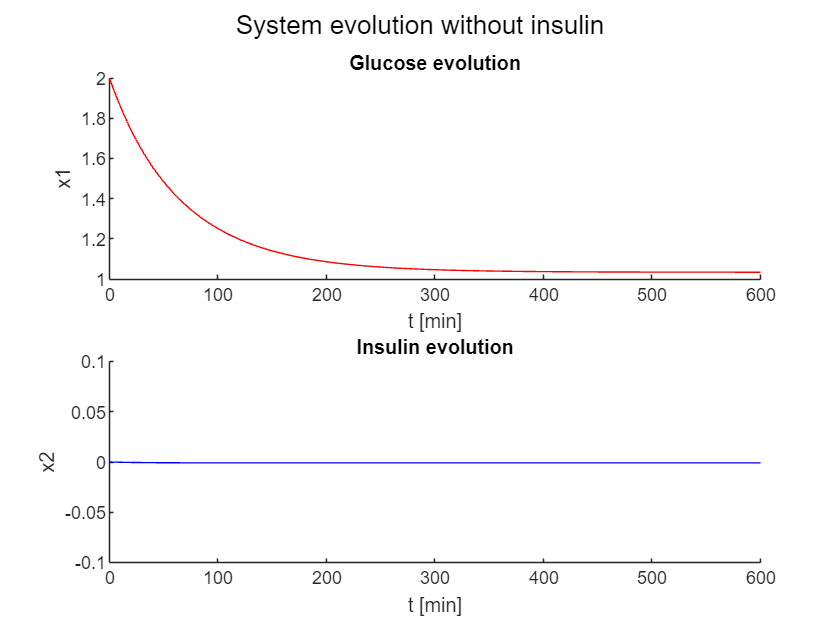

tspan = [0 600];
x0=[2 0]; %High glucose and low insulin
u=0;
[t,x] = ode45(@(t,x) SYS([x.' u]), tspan, x0);
x1=x(:,1);
x2=x(:,2);

figure;
sgtitle('System evolution without insulin')
subplot(2,1,1);
hold on;
title('Glucose evolution');
plot(t,x1,'r');
xlabel('t [min]');
ylabel('x1');
subplot(2,1,2);
hold on;
title('Insulin evolution');
plot(t,x2,'b');
xlabel('t [min]');
ylabel('x2');
ylim([-0.1 0.1]);

Osserviamo come in assenza di insulina i livello di glucosio si abbassano 

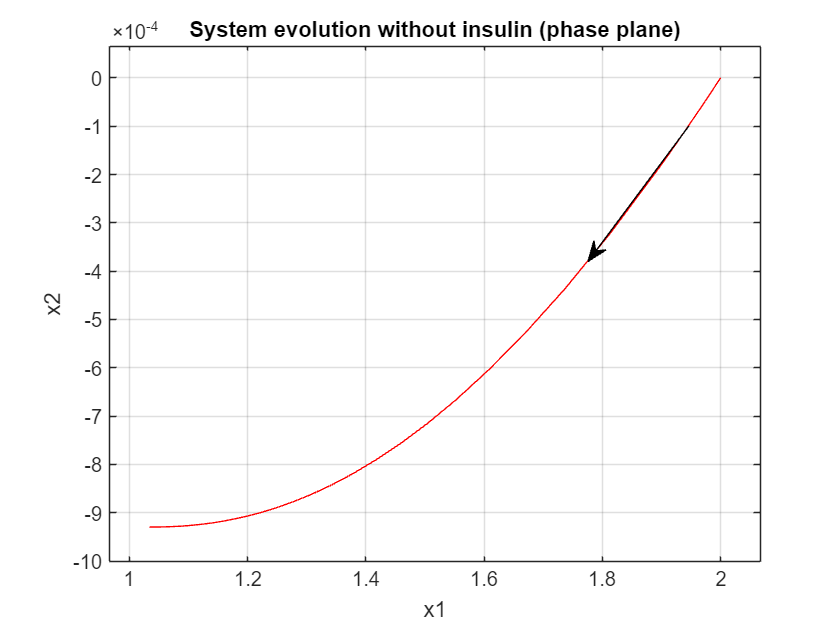

figure;
plot(x1,x2,'r');
hold on

annotation('arrow', [0.82, 0.7], [0.8 0.585])
xlabel('x1');
ylabel('x2');
axis padded
title('System evolution without insulin (phase plane)');
grid on;

stepinfo(x1,t,x1(end)) %Tempo di assestamento di circa 265min

ans = struct with fields:
         RiseTime: 0
    TransientTime: 269.2917
     SettlingTime: 264.7372
      SettlingMin: 1.0338
      SettlingMax: 2
        Overshoot: 93.4570
       Undershoot: 0
             Peak: 2
         PeakTime: 0


#### Simulazione dell'evoluzione libera del sistema a ciclo aperto con insulina

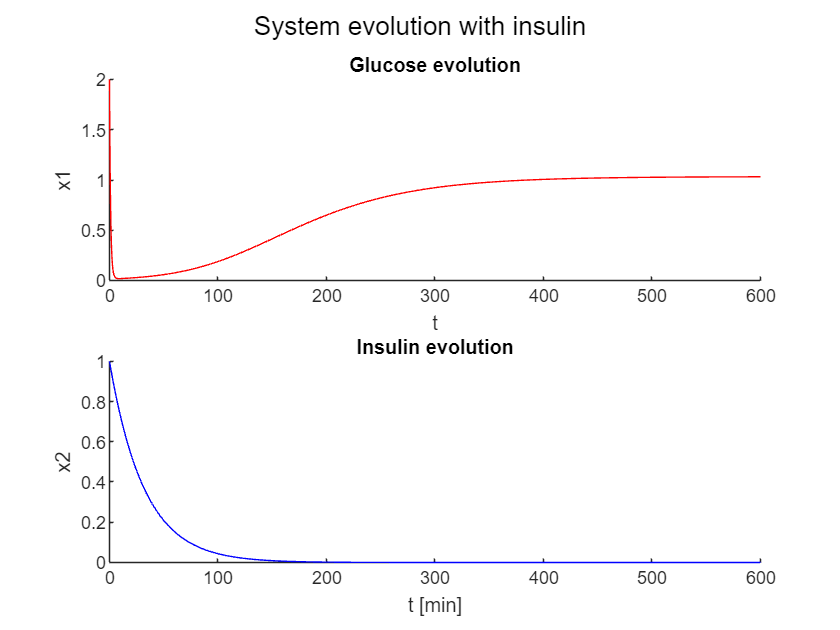

tspan = [0 600];
x0=[2 1]; %High glucose and high insulin
u=0;
[t,x] = ode45(@(t,x) SYS([x.' u]), tspan, x0);
x1=x(:,1);
x2=x(:,2);

figure;
sgtitle('System evolution with insulin')
subplot(2,1,1);
hold on;
title('Glucose evolution');
plot(t,x1,'r');
xlabel('t');
ylabel('x1');
subplot(2,1,2);
hold on;
title('Insulin evolution');
plot(t,x2,'b');
xlabel('t [min]');
ylabel('x2');

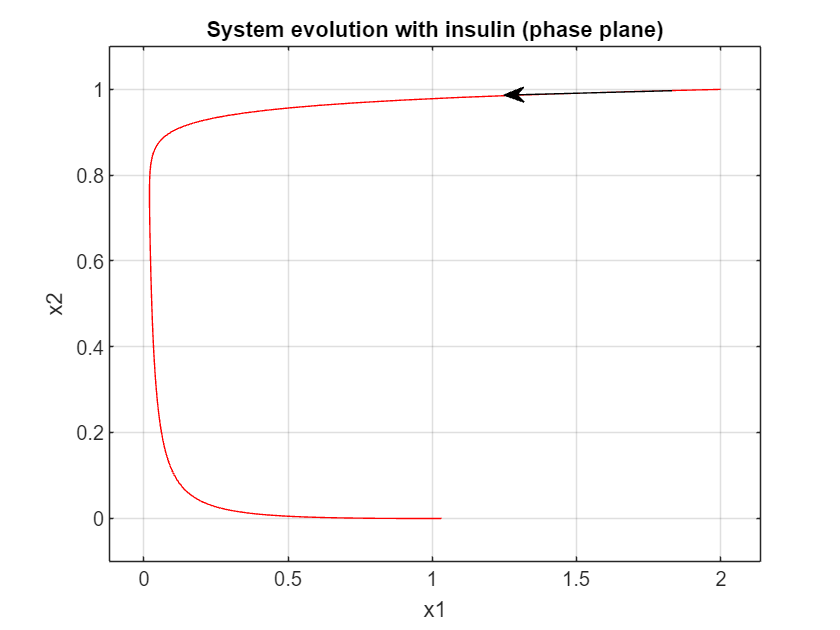

figure;
plot(x1,x2,'r');
xlabel('x1');
ylabel('x2');
axis padded
title('System evolution with insulin (phase plane)');
grid on;
annotation('arrow', [0.8, 0.60], [0.856 0.849])

stepinfo(x1,t,x1(end)) %Tempo di assestamento di circa 415min

ans = struct with fields:
         RiseTime: 0
    TransientTime: 416.7538
     SettlingTime: 415.5821
      SettlingMin: 0.0190
      SettlingMax: 2
        Overshoot: 93.7975
       Undershoot: 0
             Peak: 2
         PeakTime: 0


### Simulazione del sistema a ciclo aperto per u=1.003

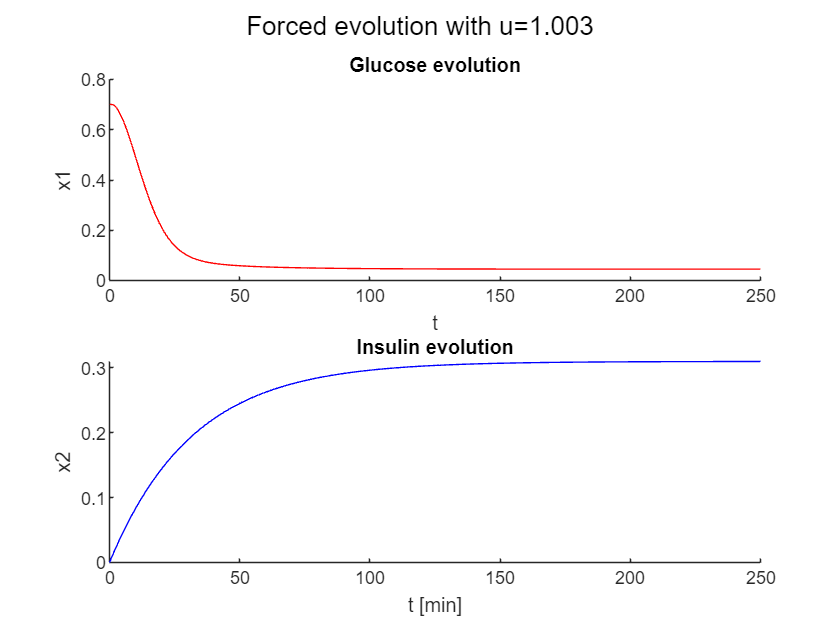

tspan = [0 250];
x0=[0.7 0];
u=1.003;
[t,x] = ode45(@(t,x) SYS([x.' u]), tspan, x0);
x1=x(:,1);
x2=x(:,2);

figure;
sgtitle('Forced evolution with u=1.003')
subplot(2,1,1);
hold on;
title('Glucose evolution');
plot(t,x1,'r');
xlabel('t');
ylabel('x1');
subplot(2,1,2);
hold on;
title('Insulin evolution');
plot(t,x2,'b');
xlabel('t [min]');
ylabel('x2');

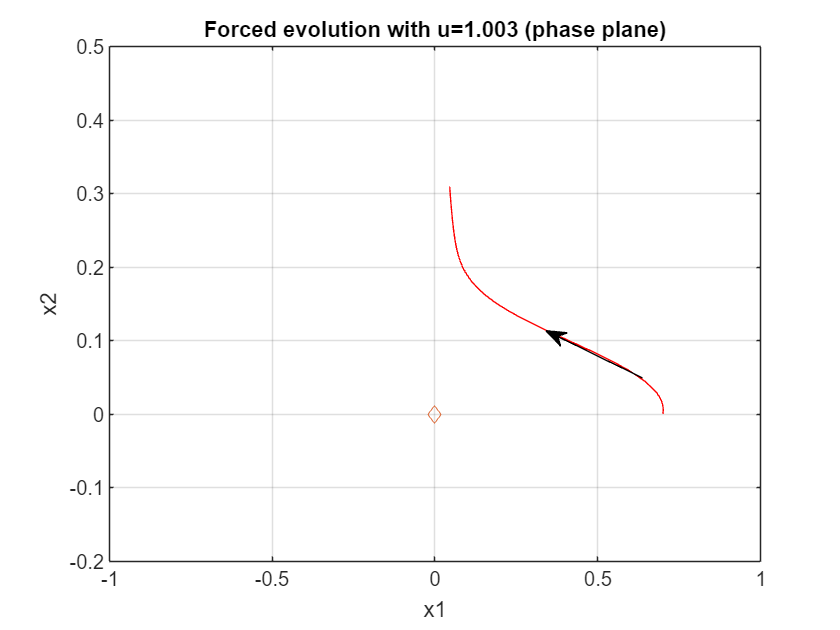

figure;
plot(x1,x2,'r', 0, 0, 'd');
xlabel('x1');
ylabel('x2');
axis padded
title('Forced evolution with u=1.003 (phase plane)');
grid on;
annotation('arrow', [0.765, 0.65], [0.4 0.475])
xlim([-1 1]);
ylim([-0.2, 0.5]);

stepinfo(x1,t,x1(end)) %Tempo di assestamento di 125min

ans = struct with fields:
         RiseTime: 0
    TransientTime: 50.8054
     SettlingTime: 126.5128
      SettlingMin: 0.0451
      SettlingMax: 0.7012
        Overshoot: 1.4551e+03
       Undershoot: 0
             Peak: 0.7012
         PeakTime: 0.6422


## Linearizzazione attorno al punto di equilibrio per u=1.003

Troviamo il punto di equilibrio per u=1.003

[x1_eq,x2_eq] = get_equilibrium(u_eq);
x1_eq,x2_eq

x1_eq = 0.0451

x2_eq = 0.3099

Linearizziamo attorno al punto di equilibrio

A = [-p1-x2_eq -x1_eq; 0 -p2];
B = [0; p3];
C = [1 0];

Gli autovalori della matrice dinamica sono:

[V,D] = eig(A);
lambda1 = D(1,1), lambda2 = D(2,2)

lambda1 = -0.3250

lambda2 = -0.0313

Gli autovalori sono entrambi a parte reale negativa allora il punto di equilibrio è asintoticamente stabile.

## Analisi del controllore v0 sul sistema linearizzato

K = [-1651800 2200];
kr = -1636751;

Calcoliamo gli autovalori della matrioce dinamica del sistema retroazionato:

[V,D] = eig(A-B*K);
lambda1 = D(1,1), lambda2 = D(2,2)

lambda1 = -10.8482 +24.7255i

lambda2 = -10.8482 -24.7255i

Quindi il sistema a ciclo chiuso è asintoticamente stabile ma la presenza di una parte immaginaria comporta la presenza di sovraelongazioni/oscillazioni. Valutiamone il coefficiente di smorzamento e la pulsazione naturale:

syms s
c_poly = sym2poly((s-lambda1)*(s-lambda2)); %The characteristic polynomial of A-BK
omega_c = sqrt(c_poly(3)), zita = c_poly(2)/(omega_c*2)

omega_c = 27.0006

zita = 0.4018

Dunque ci aspettiamo delle oscillazioni nel transitorio. Adesso visualizziamo la risposta al gradino del sistema linarizzato retroazionato col controllore v0:

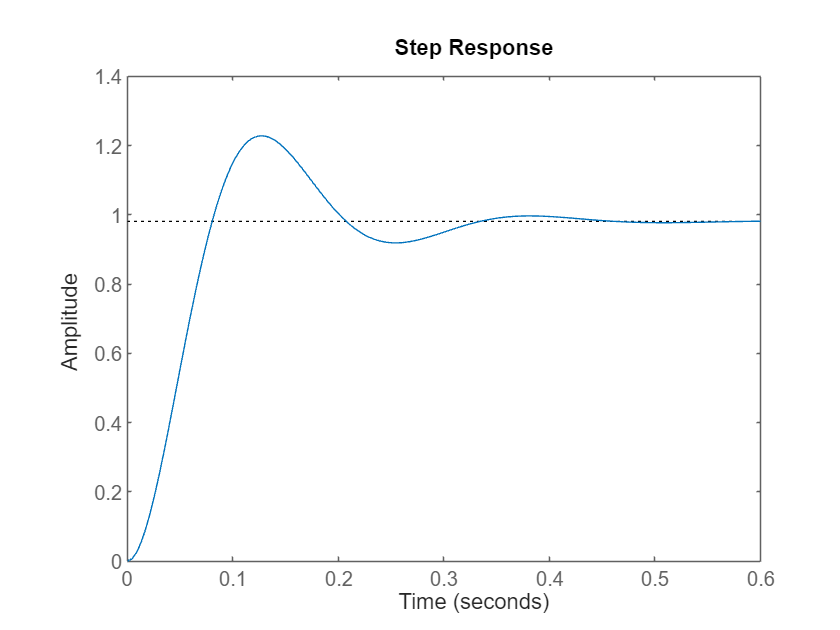

step(ss(A-B*K,B.*kr,C,0))

## Analisi del controllore v0 sul sistema non lineare

A questo punto analizziamo le performance del controllore v0 sul sistema di partenza. Con lo strumento PhasePlane abbiamo visualizzato il piano delle fasi del sistema a ciclo chiuso controllato con v0:

% Piano delle fasi a cilo chiuso per r=0.0451
matlab.apputil.run('PhasePlane');

Per visualizzare i piani delle fasi prodotti andare su 'Custom Library'>'Load' e caricare il file 'PhasePlaneLibrary.mat'. Dopodiché nel menù 'Custom Library' è possibile scegliere quale piano delle fasi visualizzare. I piani delle fasi forniti sono:

- plant-closed-loop-v0: il sistema a ciclo chiuso controllato col controllore v0. Sono state fornite due rappresentazioni dello stesso piano delle fasi.

- plant-closed-loop-v1-lqr: il sistema a ciclo chiuso controllato col controllore LQR progettato nel WP2

#### Simulazione del sistema a ciclo chiuso

Adesso simuliamo il sistema non lineare controllato col controllore v0 per valutarne le performance. Analizziamo la risposta del sistema:

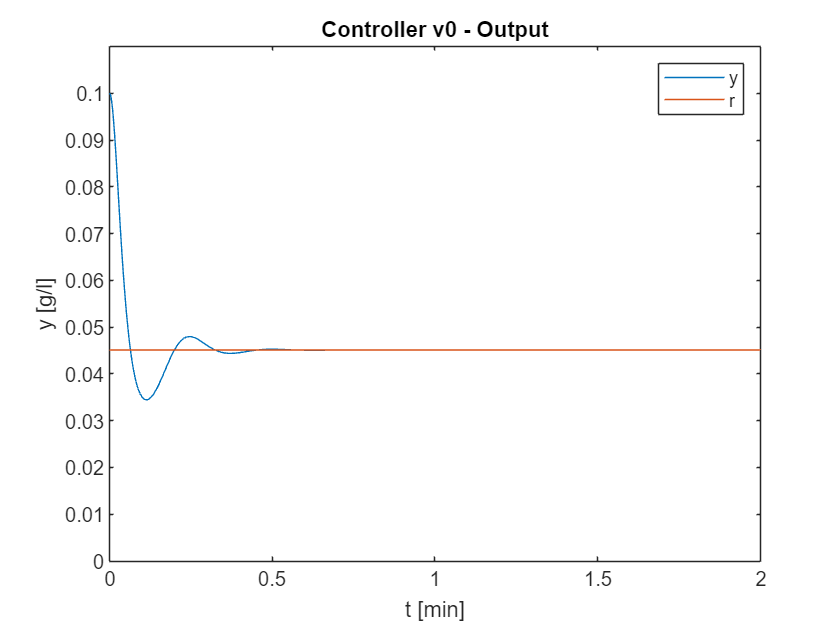

simout = sim('v0_sim.slx');
t = simout.t;
t = t.Time;
u = simout.u;
y = simout.y;
figure;
plot(t, y)
xlim([0,2])
title('Controller v0 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_info = stepinfo(y,t,x1_eq)

y_info = struct with fields:
         RiseTime: 0
    TransientTime: 0.2982
     SettlingTime: 0.3025
      SettlingMin: 0.0345
      SettlingMax: 0.1000
        Overshoot: 121.8934
       Undershoot: 0
             Peak: 0.1000
         PeakTime: 1.7631e-04


Il tempo di assestamento è apparentemente basso, essendo pari a 0.3 minuti. Tuttavia è possibile evidenziare una sottoelongazione percentuale particolarmente elevata, essendo questa pari a

percentage_undershoot = abs(min(y)-0.045102)/0.045102

percentage_undershoot = 0.2356

Adesso analizziamo lo sforzo di controllo richiesto dal controllore.

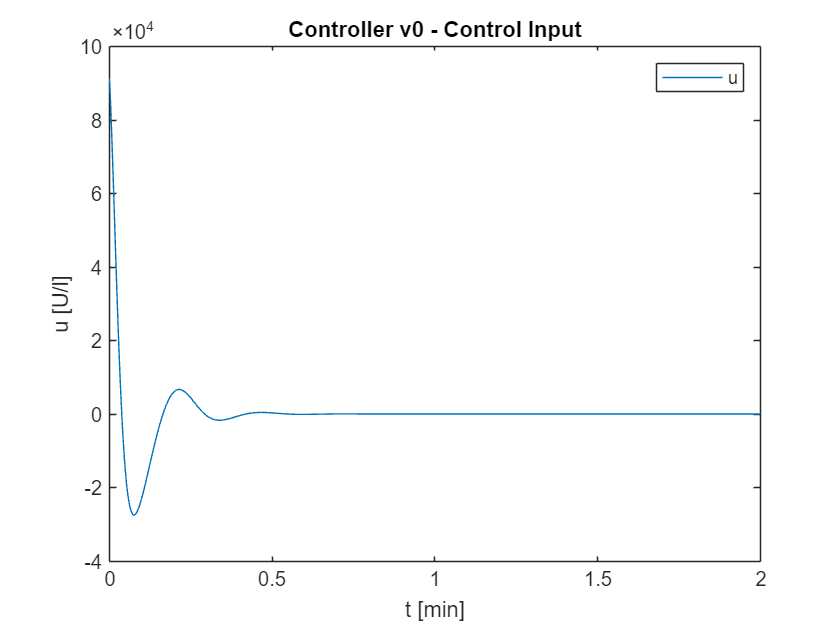

figure;
plot(t, u)
xlim([0,2])
title('Controller v0 - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_info = stepinfo(u,t,u(end))

u_info = struct with fields:
         RiseTime: 0
    TransientTime: 0.2727
     SettlingTime: 1.3857
      SettlingMin: -2.7487e+04
      SettlingMax: 9.1363e+04
        Overshoot: 9.1162e+06
       Undershoot: 2.7427e+06
             Peak: 9.1363e+04
         PeakTime: 0
